f1 = figure;
f2 = figure;
f3 = figure;
f4 = figure;


%Define Target Values
EthMdot_target = 0.27;
% EthRe_target = 27581;
LOXMdot_target = 3.3;
% LOXRe_target = 6543744;


%DEFINE REYNOLDS DATA
Ethre = [37280
38118
39226
39020
37279
31043
31893
30109
31784
31202
32001
32792
];
[EthRe, i] = sort(Ethre);
EthRe = transpose(EthRe);

LOXre = [43025
42236
38390
37327
37054
36925
36865];
[LOXRe, k] = sort(LOXre);
LOXRe = transpose(LOXRe);


%DEFINE MASS FLOW DATA
Ethmdot = [0.376
0.384
0.395
0.393
0.376
0.313
0.321
0.303
0.320
0.314
0.322
0.3686];
EthMdot = zeros(length(i), 1);

LOXmdot = [0.430
0.422
0.384
0.373
0.371
0.369
0.3686];
LOXMdot = zeros(length(k), 1);


%DEFINE Cd DATA
EthCd = [0.565
0.554
0.581
0.578
0.552
0.519
0.533
0.499
0.512
0.514
0.504
0.505];
EthCd_seq = zeros(length(i),1);

LOXCd = [0.671
0.621
0.5871
0.595
0.590
0.588
0.587];
LOXCd_seq = zeros(length(k),1);

for j = 1:length(i)
    EthCd_seq(j) = EthCd(i(j));
    EthMdot(j) = Ethmdot(i(j));
end


for d = 1:length(k)
    LOXCd_seq(d) = LOXCd(k(d));
    LOXMdot(d) = LOXmdot(k(d));
end

%SMOOTH DATA
EthCdsm = smooth(EthMdot, EthCd_seq, 0.95, 'rloess');
LOXCdsm = smooth(LOXMdot, LOXCd_seq, 0.999, 'rloess');

%INTERPOLATE/CURVE FIT
%Cdinterp = interp1(EthMdot, EthCdsm, EthMdot_target, 'log');
%[EthCdFit, p_Eth, sm_Eth, varcov_Eth] = fit_logistic(EthMdot,EthCdsm);
%Eth_Cd_target = p_Eth(2)/(1 + exp(-p_Eth(3)*(EthMdot_target-p_Eth(1))))
% 
[LOXCdFit, p_LOX, sm_LOX, varcov_LOX] = fit_logistic(LOXMdot, LOXCdsm);

max number of iterations reached...exiting
normalized epsilon: 39.6781


LOX_Cd_target = p_LOX(2)/(1 + exp(-p_LOX(3)*(LOXMdot_target-p_LOX(1))))

LOX_Cd_target = 0.6460

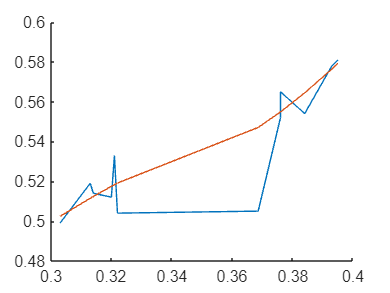

%LOXCdinterp = interp1(LOXMdot, LOXCdsm, LOXMdot_target, 'linear', 'extrap')

%figure()
% 
% hold on
% title("Reynolds vs Cd")
% plot(X,Cd_seq)
% plot(X, Cdsm)
% title("Reynolds vs Cd")
% legend("Cd Original", "Cd Smoothed")
% hold off

figure(f2)
hold on
plot(EthMdot, EthCd_seq)
plot(EthMdot, EthCdsm)

%plot(EthMdot, Cdinterp)
plot(EthMdot, EthCdFit)

Unrecognized function or variable 'EthCdFit'.

title("Ethanol Mass Flow vs Cd")
legend("Cdreal", "CdSmooth", "CdFit")
hold off

%figure(f3)
% 
% hold on
% title("LOX Reynolds vs Cd")
% plot(LOXRe,LOXCd_seq)
% plot(LOXRe, LOXCdsm)
% plot(LOXRe, LOXCDFit) 
% legend("Cd Original", "Cd Smoothed")
% hold off

figure(f4)
hold on
plot(LOXMdot, LOXCd_seq)
plot(LOXMdot, LOXCdsm)
%plot(LOXMdot, LOXCdinterp)
plot(LOXMdot, LOXCdFit)
title("LOX Mass Flow vs Cd")
legend("Cdreal", "CdSmooth", "CdFit")
hold off






function [ Qpre, p, sm, varcov] = fit_logistic(t,Q)
%fit a logistic function to time series Q(t).
%   Inputs: t (time),Q (time series variable)
%   Outputs: Qpre (logistic model fit to data) and
%   p is 3 element vector containing parameters describing the logistic:
%       thalf, Qinf, and alpha
%   Q(t) = Qinf/(1 + exp(-alpha*(t-thalf)))
%       thalf is symmetric inflection point
%       Qinf is value as t --> infinity
%       alpha is time decay constant
%   sm is 3 element vector giving 1-sigma confidence limits of parameters
%       e.g., thalf = p(1) +/- sm(1)
%       simply double the values in sm to get 95% confidence limits
%   varcov is the complete 3x3 variance-covariance matrix for investigating
%       how model paramters co-vary with each other.
%       sm is sqrt(diag(varcov))
%
%   Example:
%       Qinf = 10.2; alpha = 0.33; thalf = 108.5;
%       t = 100:120;
%       Q = Qinf./(1 + exp(-alpha*(t-thalf)));
%       noise = randn(1,length(t));
%       Qd = Q+noise;
%       Qpre = fit_logistic(t,Qd);
%       figure(1)
%       clf
%       hold on
%       plot(t,Qd,'o')  % data
%       plot(t,Qpre)    % best fitting logistic
%       
% Written by James Conder, Southern Illinois University, Oct. 2010
% Cleaned up for publishing May 16, 2013
%   May 17, 2013: Allow for decreasing logistic.
%   May 23, 2013: Fix instability when using short 
%       or long absolute times (relative to alpha = 1).
%   May 28, 2013: added example in comments, fixed an introduced bug
%       from May 23 edit. 
%   Feb 12, 2014: Revisited occasional flatlining problem.
%       (Qpre goes to mean).
%       Made initial alpha more robust. Scaled to time rather than simply
%       defaulting to one (removes much of need for rescaling time).
%       Added check for flatlining. If occurs, reset seeds with larger
%       alpha and start over.
%   Jan 25, 2016: calculate confidence limits for parameters
% equations are set up to solve for an increasing logistic.
% Check if decreasing and if so, reverse time
[~,I] = sort(t);
reverse_t = false;
if sum(diff(Q(I))) < 0      % decreasing in time
    reverse_t = true;
    t = -t;
end
% stretch short or long sequences in time to stabilize alpha
tstretch = [];
if max(t)-min(t) < 1.e-4 || max(t)-min(t) > 1e5
    tstretch = 1./(max(t) - min(t));
    t = t*tstretch;
end
% initial guesses for parameters
thalf = 0.5*(min(t) + max(t));
Qinf = max(Q);
alpha = 1./(max(t)-min(t)); alphareset = alpha;
flipQ = false;
if isrow(Q)
    flipQ = true;   % expecting a column vector. flip if row.
    t = t';
    Q = Q';
end
itermax = 1000 ;	% number of maximum iterations
epsilon = 1;
ii = 0 ;            % initialize counter
thresh = 1.e-6 ;    % threshold to stop iterating
G = zeros(length(t),3) ;    % dimensionalize partial derivative matrix
while epsilon > thresh
  ii = ii + 1 ;
  Qpre = Qinf./(1 + exp(-alpha*(t-thalf))) ;  % 'predicted' data
  if max(Qpre) - min(Qpre) == 0
      % if Qpre flatlines, "a" likely needed to be seeded higher
      % (sharper climb)
      alphareset = 2*alphareset;
      thalf = 0.5*(min(t) + max(t));
      Qinf = max(Q);
      alpha = alphareset;      
      Qpre = Qinf./(1 + exp(-alpha*(t-thalf))) ;
  end
  d = Q - Qpre ;      % data vector (predicted - observed)
  % linearized partial derivatives
  ee = min(exp(-alpha*(t-thalf)),1.e12) ;
  eee = 1./((1 + ee).^2) ;
  G(:,1) = -Qinf*alpha*(ee.*eee) ;          % dd/dthalf
  G(:,2) = 1./(1 + ee) ;                % dd/dQinf
  G(:,3) = Qinf*(t-thalf).*(ee.*eee) ;  % dd/dalpha
  
  [U,S,V] = svd(G,0);				% Singular Value Decomposition
  Sinvdiag = 1./diag(S) ;
  ising = Sinvdiag(1)./Sinvdiag < 1.e-12 ;
  Sinvdiag(ising) = 0;
  Sinv = diag(Sinvdiag);
  dm = 0.1*V*Sinv*U'*d;
							  
  % get new parameters: m = m0 + dm
  thalf = thalf + dm(1);
  Qinf = Qinf + dm(2);
  alpha = alpha + dm(3);				 
							   				  
  epsilon = norm(dm);
  if ii > itermax
	    disp('max number of iterations reached...exiting')
        disp(['normalized epsilon: ' num2str(epsilon/thresh)]) 
        epsilon = thresh ;
  end
end
Qpre = Qinf./(1 + exp(-alpha*(t-thalf))) ;  % 'predicted' data
if ~isempty(tstretch)
    thalf = thalf/tstretch;
    alpha = alpha*tstretch;
end  
if reverse_t        % decreasing logistic
    thalf = -thalf;
    alpha = -alpha;
end
if flipQ
    Qpre = Qpre';
    Q = Q';     % necessary for a posteriori variance 
end
p = [ thalf Qinf alpha ];
%%% find confidence bounds for parameters (1-sigma)
if nargout > 2
    sd = sum((Q-Qpre).^2)/(length(Q)-3);       % a posteriori variance
    varcov = sd*sd*inv(G'*G);   % model variance-covariance matrix
    sm = sqrt(diag(varcov));    % model variance
end
end
